# Main Script

## Initialization

clear
close all
clc


## Model Parameters Loading

Model_Parameters;

## Controller Parameters Definition & Controller Tune

% Current Controller
Ri.wb = 100;        % current bandwidth         [rad/s]
Ri.mphi = 60;       % current phase margin      [deg]
% Ri.tr = 1e-2;
% Ri.mp = 0.25;


% Speed Controller
Rw.wb = 50;        % speed bandwith            [rad/s]
Rw.mphi = 90;       % speed phase margin        [deg]
% Rw.tr = 4e-2;
% Rw.mp = 0.05;


% Position Controller
Rt.wb = 10;          % position bandwith         [rad/s]
Rt.mphi = 90;       % position phase margin     [deg]
% Rt.tr = 7e-2;
% Rt.mp = 0.01;


% Tune
Controller_Tune;
% Controller_Tune_2;
% Controller_Tune_3;
% LQR_Tune;

Ri, Rw, Rt%, Cw

Ri = struct with fields:
      wb: 100
    mphi: 60
     Tpi: 0.0024
      Ki: 60.9018
      Kp: 0.1437


Rw = struct with fields:
      wb: 50
    mphi: 90
     Tpi: 0.1673
      Ki: 0.6932
      Kp: 0.1159


Rt = struct with fields:
      wb: 10
    mphi: 90
     Tpi: 0.5938
      Ki: 15.4382
      Kp: 9.1670


## Debug Plot of TFs

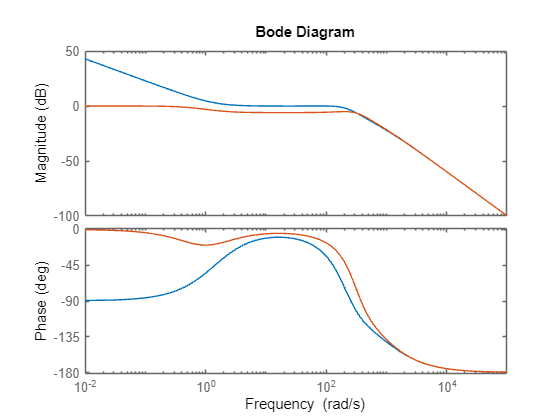

% Current Loop

bode(Li, Gi);

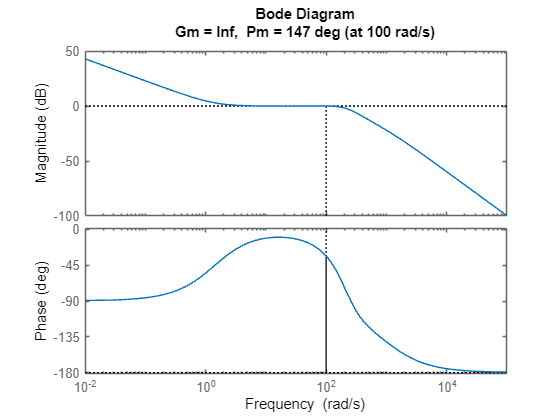

margin(Li);

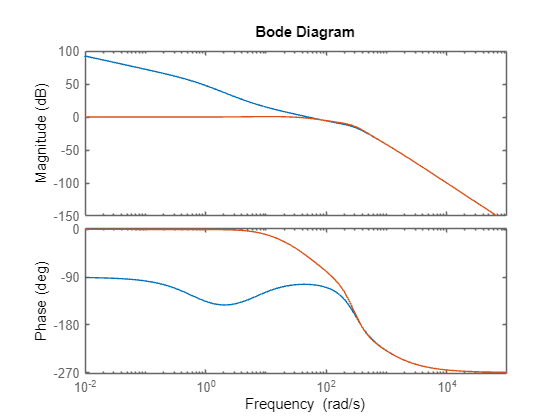

% Speed Loop

figure(2)
bode(Lw, Gw)

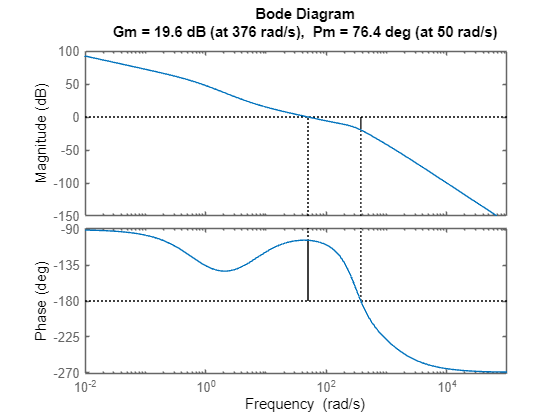

margin(Lw);

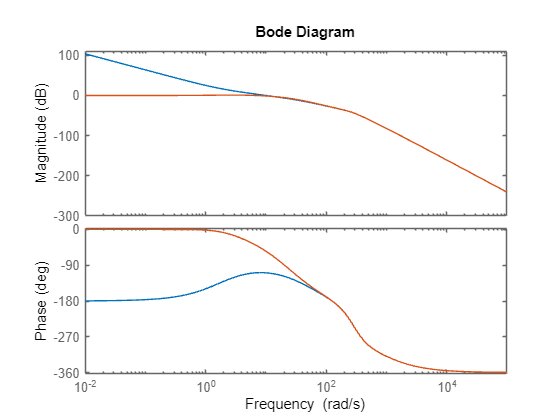

% Position Loop

figure(3)
bode(Lt, Gt)

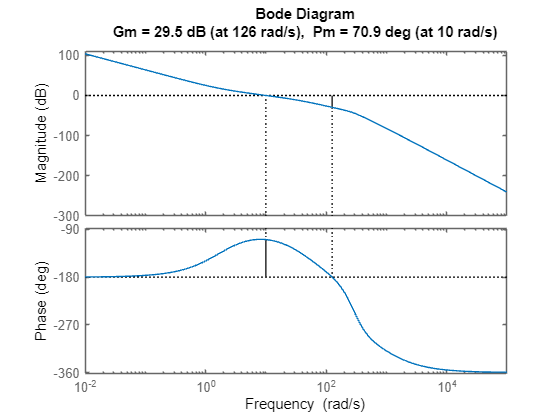

margin(Lt);

## Observer Choice & Tune

% Simple Observer

% Observer_Tune;


% Kalman Filter (4 states)

Kalman_Tune;